# Generación de trayectorias

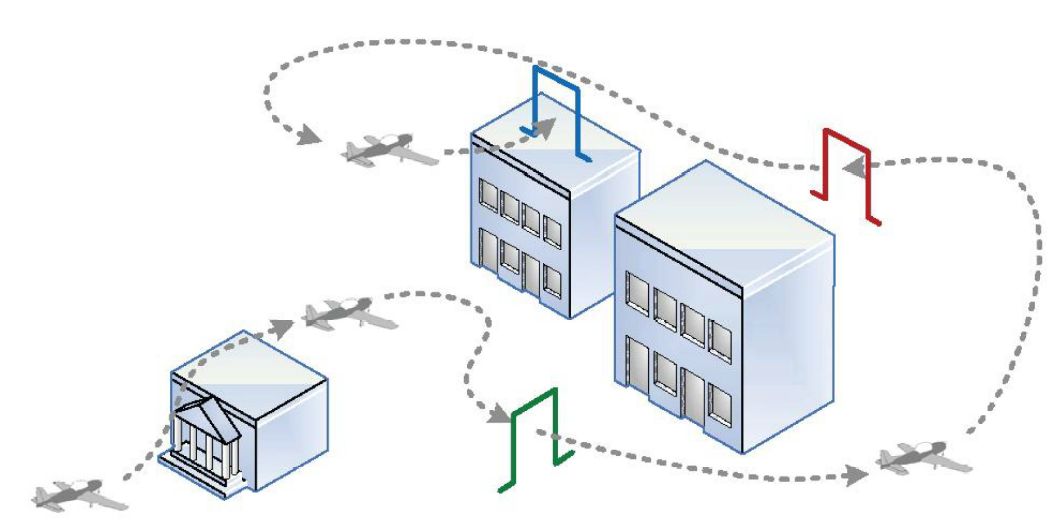

El objetivo de la generación es obtener una función que satisfaga las condiciones de frontera, es decir que cumpla con los requisitos de posición, velocidad, aceleración etc.

Estas condiciones son conocidas por el usuario 

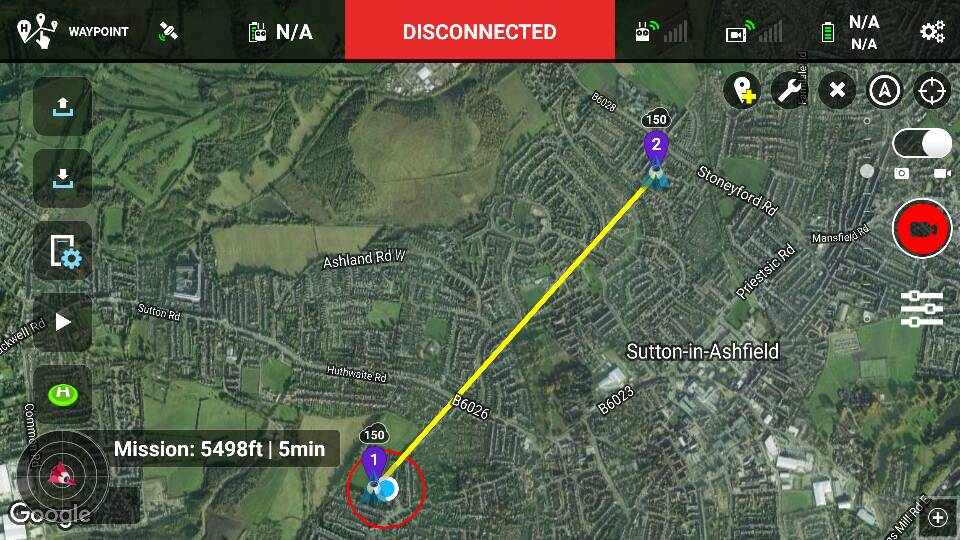

Por ejemplo:

Punto 1:

UAV en el suelo

Posición (x,y,z,yaw)=(0,0,0,0)

Velocidad (x,y,z,yaw)=(0,0,0,0)

Punto 2:

UAV en vuelo estacionario

Posición (x,y,z,yaw)=(10,10,10,0)

Velocidad (x,y,z,yaw)=(0,0,0,0)

El objetivo entonces, es obtener todos los puntos que componen la línea amarilla de la figura de arriba. La manera más simple de resolver este problema es utilizar polinomios de grado adecuado.

El grado del polinomio depende directamente del número de condiciones de frontera.

Supongamos que queremos obtener la trayectoria de la imagen anterior, y que queremos controlar sólo posición y velocidad. Por lo tanto las condiciones de frontera para posición en X son las siguientes:

Punto 1:

UAV en el suelo (X inicial)

Posición; xini=0;

Velocidad vxini=0;

Punto 2:

UAV en vuelo estacionario (X final)

Posición; xf=10;

Velocidad vxf=0;

Tomando en cuenta estos datos tenemos 4 condiciones de frontera, por lo tanto para resolver el problema tenemos que generar al menos un polinomio de grado 3.

Nuestro problema entonces se resume a obtener los valores de los coeficientes.

Para obtenerlos es necesario generar un sistema de ecuaciones como sigue:

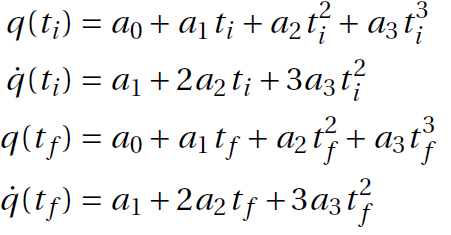

Las primeras dos ecuaciones están relacionadas con la posición y la velocidad inicial, las últimas dos dependen de la posición y la velocidad final. Es necesaria una ecuación por cada condición de frontera.

Sabiendo que el tiempo inicial, ti=0 y sustituyendo en las primeras dos ecuaciones

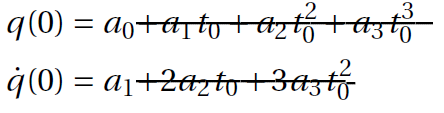

Es posible obtener los coeficientes a0 y a1 de forma simple, ya que 


$$\begin{array}{l}
Posición\text{ }inicial=q\left(0\right)=a_0 =0\\
Velocidad\text{ }inicial=\overset{\ldotp }{q} \left(0\right)=a_1 =0
\end{array}$$


Para obtener los valores de los coeficientes faltantes (a2 y a3) es necesario usar las ecuaciones relacionadas con el tiempo final. Por lo tanto y de acuerdo a los datos del problema


$$Posición\text{ }final=q\left(tf\right)=10=a_0 +a_1 tf+a_2 {tf}^2 +a_3 {tf}^3$$


Donde:

a0=0

a1=0

Por lo tanto


$$q\left(\text{tf}\right)=0+0+a_2 {\text{tf}}^2 +a_3 {\text{tf}}^3 =10$$


Realizando las mismas sustituciones en la ecuación de velocidad final, obtenemos:


$$\overset{\ldotp }{q\left(tf\right)} =0+2a_2 tf+3a_3 {tf}^2 =0$$


Por to tanto para obtener los coeficientes faltantes es necesario resolver un sistema de dos ecuaciones con dos incógnitas.

Para hacer esto es necesario acomodar las ecuaciones anteriores para que tengan la forma convencional


$$AX=B$$


Donde:

A= Matriz cuadrada formada por los valores que dependen del tiempo (tf´s)

X=Vector de los coeficientes a encontrar.

B=Resultados y valores conocidos en cada una de las ecuaciones.

Para nuestro caso particular el sistema de ecuaciones a resolver es:


$$\left\lbrack \begin{array}{c}
{tf}^2  & tf\\
2tf & 3{tf}^2 
\end{array}\right\rbrack ∗\left\lbrack \begin{array}{c}
a_2 \\
a_3 
\end{array}\right\rbrack =\left\lbrack \begin{array}{c}
10\\
0
\end{array}\right\rbrack$$


Por lo tanto el sistema puede ser resuelto de la siguiente manera:


$$\text{X}=A^{−1} B$$


El código en Matlab será entonces el siguiente

tf=150% Número de puntos de la trayectoria

tf = 150

A=[tf^2 tf^3; 2*tf 3*tf^2]

A =        22500     3375000
         300       67500


%% Para "x"
xd=10 % Posición final deseada en x 

xd = 10

xpd=0% Velocidad final deseada en x

xpd = 0

a0=0  %Condicion inicial en x posición

a0 = 0

a1=0  %Condicion initial en x velocidad

a1 = 0

B=[10;0]

B =     10
     0


coef=(inv(A))*B

coef =     0.0013
   -0.0000


a2=coef(1)

a2 = 0.0013

a3=coef(2)

a3 = -5.9259e-06

rev=A*coef

rev =    10.0000
   -0.0000


    Una vez que obtuvimos los coeficientes de los polinomios es necesario generar la trayectoria a seguir, para esto es necesario obtener el valor de posición y velocidad de cada uno de los puntos que la componen.

for n=1:1:tf
    %%  Cálculo de todos los puntos de la trayectoria
    px(n)=a0+a1*n+a2*n^2+a3*n^3; %Posición de X
    vx(n)=a1+2*a2*n+3*a3*n^2; %Velocidad de X
    t(n)=n;
    
end

Para verificar el resultado, es necesario graficar ambas trayectorias.

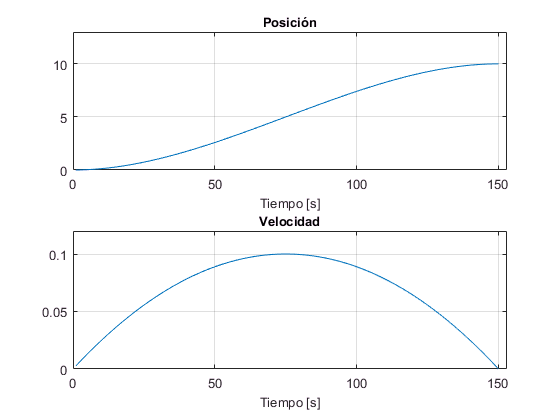

figure('Name','Trayectorias en X','NumberTitle','off')
subplot(2,1,1)
plot(t,px)
axis([0 tf+3 0 xd+3]) 
xlabel('Tiempo [s]','FontSize',10)
ylabel('')
title('Posición','FontSize',10)
grid on
%%%%%%%%%%%%%%%%%%%%%%%%%%%%
subplot(2,1,2)
plot(t,vx)
axis([0 tf+3 0 0.12]) 
xlabel('Tiempo [s]','FontSize',10)
ylabel('')
title('Velocidad','FontSize',10)
grid on